data1 = readtable("sa7035.dat")

data1 = 81×2 table
     Var1       Var2  
    _______    _______

          1          0
    0.99815    0.00017
    0.99265    0.00079
    0.98367    0.00197
    0.97138    0.00375
      0.956    0.00615
    0.93777    0.00913
    0.91689    0.01264
    0.89359    0.01657
    0.86806    0.02082
    0.84049    0.02528
    0.81106    0.02984
    0.77993    0.03442
    0.74727    0.03894
    0.71326    0.04334
     0.6781     0.0476


x_loc = table2array(data1(:,"Var1"))

x_loc =     1.0000
    0.9981
    0.9927
    0.9837
    0.9714
    0.9560
    0.9378
    0.9169
    0.8936
    0.8681


y_loc = table2array(data1(:,"Var2"))

y_loc =          0
    0.0002
    0.0008
    0.0020
    0.0037
    0.0062
    0.0091
    0.0126
    0.0166
    0.0208


data2 = readtable("T2_Re0.278_M0.00_N9.0.xlsx")

data2 = 146×12 table
    alpha      CL        CD         CDp        Cm       TopXtr    BotXtr     Cpmin     Chinge    XCp    Var11    Var12 
    _____    ______    _______    _______    _______    ______    ______    _______    ______    ___    _____    ______

    -2.6     0.0214     0.0067    0.00155    -0.0627    0.7782    0.0052    -1.8911      0        0       0       3.211
    -2.5     0.0343    0.00688    0.00153    -0.0631    0.8003    0.0053    -1.7904      0        0       0      2.1046
    -2.4     0.0463    0.00703     0.0015    -0.0632    0.8092    0.0055     -1.691      0

Airfoil plot

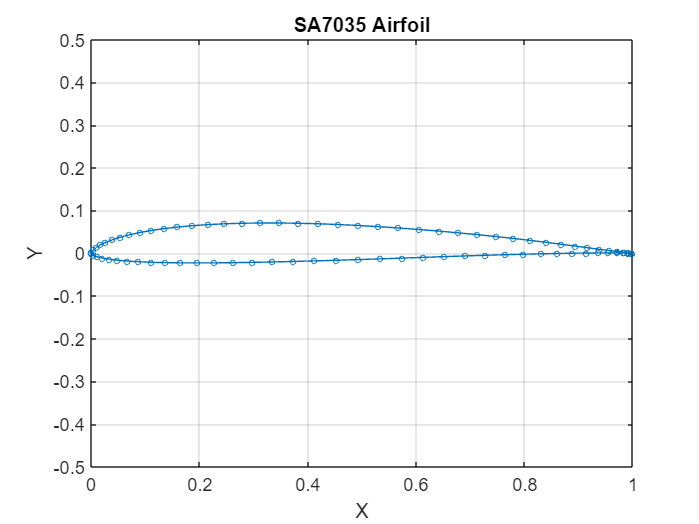

figure()
p = plot(x_loc,y_loc,'-o');
p.MarkerSize = 3;
xlim([0,1])
ylim([-0.5,0.5])
xlabel("X")
ylabel("Y")
title("SA7035 Airfoil")
grid on
saveas(gcf,'Airfoil.png')

alpha = table2array(data2(:,"alpha"))

alpha =    -2.6000
   -2.5000
   -2.4000
   -2.3000
   -2.2000
   -2.1000
   -2.0000
   -1.9000
   -1.8000
   -1.7000


C_L = table2array(data2(:,"CL"))

C_L =     0.0214
    0.0343
    0.0463
    0.0583
    0.0704
    0.0822
    0.0939
    0.1054
    0.1169
    0.1284


C_D = table2array(data2(:,"CD"))

C_D =     0.0067
    0.0069
    0.0070
    0.0071
    0.0072
    0.0073
    0.0074
    0.0074
    0.0075
    0.0075


C_Dp = table2array(data2(:,"CDp"))

C_Dp =     0.0015
    0.0015
    0.0015
    0.0015
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014


C_m = table2array(data2(:,"Cm"))

C_m =    -0.0627
   -0.0631
   -0.0632
   -0.0634
   -0.0635
   -0.0636
   -0.0637
   -0.0638
   -0.0639
   -0.0639


Xtr_top = table2array(data2(:,"TopXtr"))

Xtr_top =     0.7782
    0.8003
    0.8092
    0.8151
    0.8194
    0.8217
    0.8228
    0.8229
    0.8224
    0.8214


Xtr_bot = table2array(data2(:,"BotXtr"))

Xtr_bot =     0.0052
    0.0053
    0.0055
    0.0058
    0.0062
    0.0067
    0.0074
    0.0082
    0.0093
    0.0130


Min_Cp = table2array(data2(:,"Cpmin"))

Min_Cp =    -1.8911
   -1.7904
   -1.6910
   -1.5904
   -1.4890
   -1.3877
   -1.2859
   -1.1847
   -1.0889
   -1.0044


figure()
p2 = plot(alpha,C_L,Color='blue')

p2 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.6000 -2.5000 -2.4000 -2.3000 -2.2000 -2.1000 -2 -1.9000 -1.8000 -1.7000 -1.6000 -1.5000 -1.4000 -1.3000 -1.2000 -1.1000 -1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 … ] (1×146 double)
              YData: [0.0214 0.0343 0.0463 0.0583 0.0704 0.0822 0.0939 0.1054 0.1169 0.1284 0.1391 0.1498 0.1605 0.1712 0.1818 0.1924 0.2024 0.2103 0.2175 0.2263 0.2356 0.2445 0.2532 0.2622 0.2719 0.2838 0.2989 0.3166 0.3361 0.3555 … ] (1×146 double)

  Show <a href="matlab:if exist('p2', 'var'), matlab.graphics.internal.getForDisplay('p2', p2, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p2'), end">all properties</

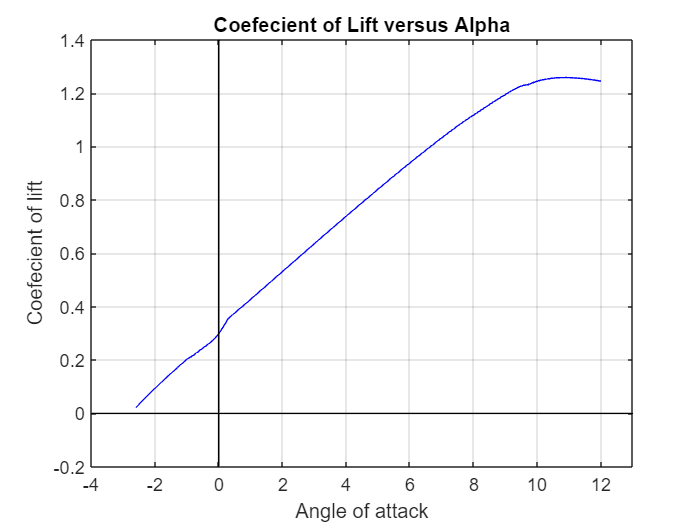

grid on 
ylim([-0.2,1.4])
xlim([-4,13])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("Angle of attack")
ylabel("Coefecient of lift")
title("Coefecient of Lift versus Alpha")
saveas(gcf,'Cl_alpha.png')

figure()
p3 = plot(alpha,C_D,Color='blue')

p3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.6000 -2.5000 -2.4000 -2.3000 -2.2000 -2.1000 -2 -1.9000 -1.8000 -1.7000 -1.6000 -1.5000 -1.4000 -1.3000 -1.2000 -1.1000 -1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 … ] (1×146 double)
              YData: [0.0067 0.0069 0.0070 0.0071 0.0072 0.0073 0.0074 0.0074 0.0075 0.0075 0.0073 0.0072 0.0070 0.0069 0.0067 0.0066 0.0063 0.0057 0.0054 0.0053 0.0053 0.0053 0.0053 0.0053 0.0053 0.0054 0.0054 0.0055 0.0056 0.0056 … ] (1×146 double)

  Show <a href="matlab:if exist('p3', 'var'), matlab.graphics.internal.getForDisplay('p3', p3, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p3'), end">all properties</

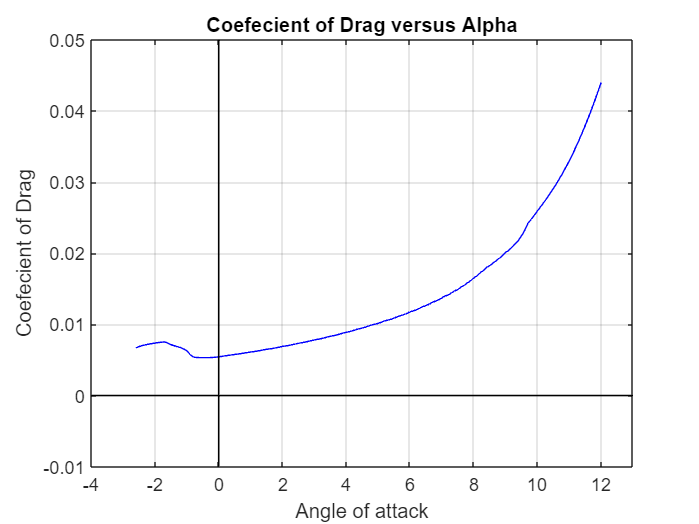

grid on 
ylim([-0.01,0.05])
xlim([-4,13])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("Angle of attack")
ylabel("Coefecient of Drag")
title("Coefecient of Drag versus Alpha")
saveas(gcf,'Cd_alpha.png')

figure()
p3 = plot(C_L,C_D,Color='blue')

p3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0214 0.0343 0.0463 0.0583 0.0704 0.0822 0.0939 0.1054 0.1169 0.1284 0.1391 0.1498 0.1605 0.1712 0.1818 0.1924 0.2024 0.2103 0.2175 0.2263 0.2356 0.2445 0.2532 0.2622 0.2719 0.2838 0.2989 0.3166 0.3361 0.3555 … ] (1×146 double)
              YData: [0.0067 0.0069 0.0070 0.0071 0.0072 0.0073 0.0074 0.0074 0.0075 0.0075 0.0073 0.0072 0.0070 0.0069 0.0067 0.0066 0.0063 0.0057 0.0054 0.0053 0.0053 0.0053 0.0053 0.0053 0.0053 0.0054 0.0054 0.0055 0.0056 0.0056 … ] (1×146 double)

  Show all properties


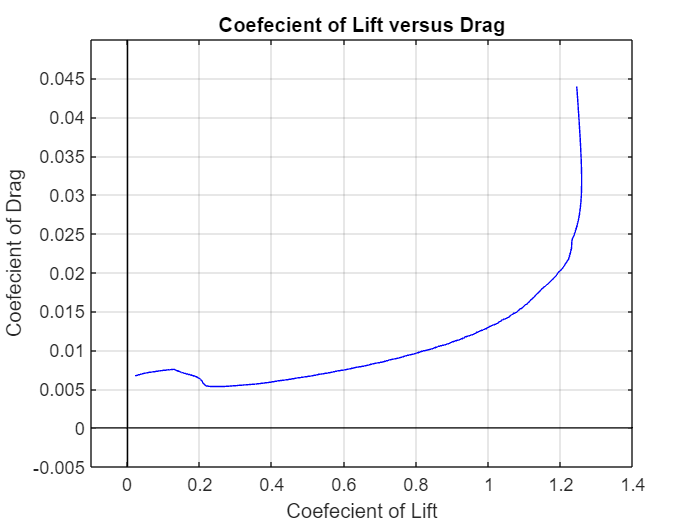

grid on 
ylim([-0.005,0.05])
xlim([-0.1,1.4])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("Coefecient of Lift")
ylabel("Coefecient of Drag")
title("Coefecient of Lift versus Drag")
saveas(gcf,'Cl_Cd.png')

Cl_Cd = C_L./C_D

Cl_Cd =     3.1940
    4.9855
    6.5861
    8.1767
    9.7507
   11.2603
   12.7236
   14.1667
   15.5867
   17.0292


figure()
p3 = plot(alpha,Cl_Cd,Color='blue')

p3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.6000 -2.5000 -2.4000 -2.3000 -2.2000 -2.1000 -2 -1.9000 -1.8000 -1.7000 -1.6000 -1.5000 -1.4000 -1.3000 -1.2000 -1.1000 -1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 … ] (1×146 double)
              YData: [3.1940 4.9855 6.5861 8.1767 9.7507 11.2603 12.7236 14.1667 15.5867 17.0292 18.9252 20.9510 22.9286 24.9199 27.0134 29.3293 32.2807 36.6376 40.1292 42.2991 44.2026 45.8724 47.5047 49.1932 50.8224 52.6531 54.9449 … ] (1×146 double)

  Show <a href="matlab:if exist('p3', 'var'), matlab.graphics.internal.getForDisplay('p3', p3, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p3'), end">all properties<

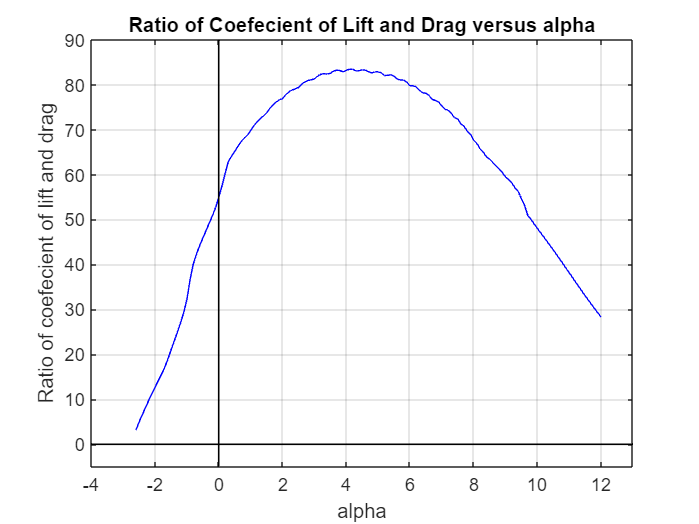

grid on 
ylim([-5,90])
xlim([-4,13])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("alpha")
ylabel("Ratio of coefecient of lift and drag")
title("Ratio of Coefecient of Lift and Drag versus alpha")
saveas(gcf,'Cl_Cd_ratio.png')

data3 = readtable("Polar_Graph_1.csv")

data3 = 126×16 table
    Alpha    SA7035_without_flap    Var3    Alpha_1    SA7035__10_flap    Var6    Alpha_2    SA7035__20_flap    Var9    Alpha_3    SA7035_10_flap    Var12    Alpha_4    SA7035__10_flap_1    Var15_1    Var16_1
    _____    ___________________    ____    _______    _______________    ____    _______    _______________    ____    _______    ______________    _____    _______    _________________    _______    _______

    -4.9        

alpha_noflaps = rmmissing(table2array(data3(:,"Alpha")))

alpha_noflaps =    -4.9000
   -4.8000
   -4.7000
   -4.6000
   -4.5000
   -4.0000
   -3.9000
   -3.8000
   -3.7000
   -3.6000


alpha__20 = rmmissing(table2array(data3(:,"Alpha_2")))

alpha__20 =    -4.9000
   -4.8000
   -4.7000
   -4.6000
   -4.5000
   -4.4000
   -4.3000
   -4.2000
   -4.1000
   -4.0000


alpha__10 = rmmissing(table2array(data3(:,"Alpha_1")))

alpha__10 =    -5.0000
   -4.9000
   -4.8000
   -4.7000
   -4.6000
   -4.5000
   -4.4000
   -4.3000
   -4.2000
   -4.1000


alpha_10 = rmmissing(table2array(data3(:,"Alpha_3")))

alpha_10 =    -5.0000
   -4.9000
   -4.7000
   -4.6000
   -4.5000
   -4.4000
   -4.3000
   -4.2000
   -4.1000
   -4.0000


alpha_20 = rmmissing(table2array(data3(:,"Alpha_4")))

alpha_20 =    -5.0000
   -4.9000
   -4.8000
   -4.7000
   -4.6000
   -4.5000
   -4.4000
   -4.3000
   -4.2000
   -4.1000



CL__20 = rmmissing(table2array(data3(:,"SA7035__20_flap")))

CL__20 =    -0.8046
   -0.8072
   -0.8100
   -0.8133
   -0.8166
   -0.8204
   -0.8244
   -0.8284
   -0.8325
   -0.8367


CL__10 = rmmissing(table2array(data3(:,"SA7035__10_flap")))

CL__10 =    -0.6204
   -0.6182
   -0.6158
   -0.6132
   -0.6107
   -0.6077
   -0.6042
   -0.6006
   -0.5968
   -0.5927


CL_0 = rmmissing(table2array(data3(:,"SA7035_without_flap")))

CL_0 =    -0.3444
   -0.3308
   -0.3164
   -0.3009
   -0.2853
   -0.2086
   -0.1897
   -0.1713
   -0.1601
   -0.1471


CL_10 = rmmissing(table2array(data3(:,"SA7035_10_flap")))

CL_10 =    -0.0828
   -0.0739
   -0.0391
   -0.0233
   -0.0081
    0.0068
    0.0215
    0.0360
    0.0502
    0.0706


CL_20 = rmmissing(table2array(data3(:,"SA7035__10_flap_1")))

CL_20 =     0.3098
    0.3299
    0.3453
    0.3618
    0.3744
    0.3880
    0.4006
    0.4127
    0.4227
    0.4348


figure()
p4 = plot(alpha__20,CL__20,Color='red',DisplayName=('-20^{\circ} Flap angle'))

p4 =   Line (-20^{\circ} Flap angle) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-4.9000 -4.8000 -4.7000 -4.6000 -4.5000 -4.4000 -4.3000 -4.2000 -4.1000 -4 -3.9000 -3.8000 -3.7000 -3.6000 -3.5000 -3.4000 -3.3000 -3.2000 -3.1000 -3 -2.9000 -2.8000 -2.7000 -2.6000 -2.5000 -2.4000 -2.3000 -2.2000 … ] (1×119 double)
              YData: [-0.8046 -0.8072 -0.8100 -0.8133 -0.8166 -0.8204 -0.8244 -0.8284 -0.8325 -0.8367 -0.8409 -0.8454 -0.8483 -0.8508 -0.8528 -0.8546 -0.8560 -0.8572 -0.8580 -0.8700 -0.8776 -0.8799 -0.8780 -0.8761 -0.8742 -0.8722 … ] (1×119 double)

  Show 

hold on 
p5 = plot(alpha__10,CL__10,Color='green',DisplayName=('-10^{\circ} Flap angle'))

p5 =   Line (-10^{\circ} Flap angle) with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-5 -4.9000 -4.8000 -4.7000 -4.6000 -4.5000 -4.4000 -4.3000 -4.2000 -4.1000 -4 -3.9000 -3.8000 -3.7000 -3.5000 -3.4000 -3.3000 -3.2000 -3.1000 -3 -2.9000 -2.8000 -2.7000 -2.6000 -2.5000 -2.1000 -2 -1.9000 -1.8000 … ] (1×122 double)
              YData: [-0.6204 -0.6182 -0.6158 -0.6132 -0.6107 -0.6077 -0.6042 -0.6006 -0.5968 -0.5927 -0.5884 -0.5832 -0.5757 -0.5623 -0.5504 -0.5599 -0.5535 -0.5468 -0.5402 -0.5334 -0.5262 -0.5181 -0.5096 -0.5001 -0.4838 -0.4625 … ] (1×122 double)

  Show 

hold on 
p6 = plot(alpha_noflaps,CL_0,Color='blue',DisplayName=('0^{\circ} Flap angle'))

p6 =   Line (0^{\circ} Flap angle) with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-4.9000 -4.8000 -4.7000 -4.6000 -4.5000 -4 -3.9000 -3.8000 -3.7000 -3.6000 -3.5000 -3.4000 -3.3000 -3.2000 -3.1000 -3 -2.9000 -2.8000 -2.7000 -2.6000 -2.5000 -2.4000 -2.3000 -2.2000 -2.1000 -2 -1.9000 -1.8000 … ] (1×126 double)
              YData: [-0.3444 -0.3308 -0.3164 -0.3009 -0.2853 -0.2086 -0.1897 -0.1713 -0.1601 -0.1471 -0.1328 -0.1177 -0.1020 -0.0857 -0.0688 -0.0514 -0.0333 -0.0231 -0.0093 0.0064 0.0225 0.0388 0.0545 0.0688 0.0809 0.0880 0.0989 … ] (1×126 double)

  Show 

hold on 
p7 = plot(alpha_10,CL_10,Color='cyan',DisplayName=('10^{\circ} Flap angle'))

p7 =   Line (10^{\circ} Flap angle) with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-5 -4.9000 -4.7000 -4.6000 -4.5000 -4.4000 -4.3000 -4.2000 -4.1000 -4 -3.9000 -3.8000 -3.7000 -3.6000 -3.5000 -3.4000 -3.3000 -3.2000 -3.1000 -3 -2.9000 -2.7000 -2.6000 -2.5000 -2.4000 -2.2000 -2.1000 -2 -1.9000 … ] (1×119 double)
              YData: [-0.0828 -0.0739 -0.0391 -0.0233 -0.0081 0.0068 0.0215 0.0360 0.0502 0.0706 0.0947 0.1169 0.1395 0.1601 0.1831 0.2052 0.2267 0.2429 0.2591 0.2746 0.2912 0.3162 0.3330 0.3497 0.3679 0.3900 0.4061 0.4225 0.4401 … ] (1×119 double)

  Show 

hold on 
p8 = plot(alpha_20,CL_20,Color='magenta',DisplayName=('20^{\circ} Flap angle'))

p8 =   Line (20^{\circ} Flap angle) with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-5 -4.9000 -4.8000 -4.7000 -4.6000 -4.5000 -4.4000 -4.3000 -4.2000 -4.1000 -4 -3.9000 -3.8000 -3.7000 -3.6000 -3.5000 -3.4000 -3.3000 -3.2000 -3.1000 -3 -2.9000 -2.8000 -2.7000 -2.6000 -2.5000 -2.3000 -2.2000 … ] (1×125 double)
              YData: [0.3098 0.3299 0.3453 0.3618 0.3744 0.3880 0.4006 0.4127 0.4227 0.4348 0.4481 0.4599 0.4722 0.4795 0.4928 0.5063 0.5192 0.5324 0.5366 0.5508 0.5660 0.5824 0.5852 0.6001 0.6158 0.6322 0.6546 0.6737 0.6946 0.7079 … ] (1×125 double)

  Show 

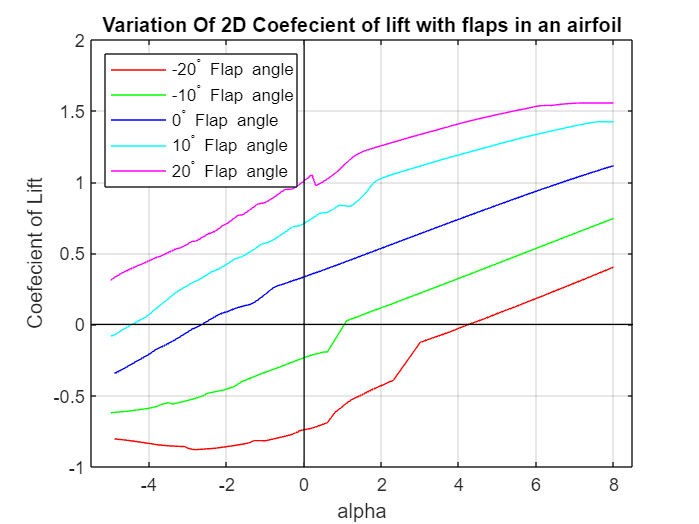

grid on 
ylim([-1,2])
xlim([-5.5,8.5])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("alpha")
ylabel("Coefecient of Lift")
title("Variation Of 2D Coefecient of lift with flaps in an airfoil")
legend([p4,p5,p6,p7,p8],Location='northwest')
saveas(gcf,'Flaps.png')